clc
clear

## Substituting values for our M, m1, m2, l1 and l2

M=1000;
m1=100;
m2=100;
l1=20;
l2=10;
g=9.81;

## Declaring the state space matrices

A=[0 1 0 0 0 0;
 0 0 -(m1*g)/M 0 -(m2*g)/M 0;
 0 0 0 1 0 0;
 0 0 -((M+m1)*g)/(M*l1) 0 -(m2*g)/(M*l1) 0;
 0 0 0 0 0 1;
 0 0 -(m1*g)/(M*l2) 0 -(g*(M+m2))/(M*l2) 0];

B=[0; 1/M; 0; 1/(M*l1); 0; 1/(M*l2)];

% We previously determined that only C1, C3 and C4 are observable.
% Hence we will only use C1, C3 and C4.

% Output measurement vectors

C1 = [1 0 0 0 0 0]; 
C3 = [1 0 0 0 0 0; 0 0 0 0 1 0;]; 
C4 = [1 0 0 0 0 0; 0 0 1 0 0 0; 0 0 0 0 1 0];

D = 0;

## Declaring the same Q and R matrices as done for LQR

Q = [1/12 0 0 0 0 0;
    0 1/(12*0.1) 0 0 0 0;
    0 0 1/(8*0.2^2) 0 0 0;
    0 0 0 1/(12*0.01^2) 0 0;
    0 0 0 0 1/(8*0.2^2) 0;
    0 0 0 0 0 1/(12*0.01^2)];

R = 0.00001;

## Initial Conditions for Leunberger observer - 12 state variables,

% Considering 6 actual states + 6 estimate errors as the new state
X0=[0,0,deg2rad(30),0,deg2rad(-20),0,0,0,0,0,0,0];

% state variables order = [x,dx,theta_1,dtheta_1,theta_2,dtheta_2, estimates taken in the same order]

% Calling LQR function to obtain K gain matrix
K=lqr(A,B,Q,R);

## For pole placement, lets choose eigen values with negative real part

poles=[-3;-6;-9;-12;-15;-18];
% Computing the L matrix by placing the negative poles to an even more
% negative value using place() MATLAB command

L1 = place(A',C1',poles)'; 
L3 = place(A',C3',poles)'; 
L4 = place(A',C4',poles)';

A_c1 = [(A-B*K) B*K; zeros(size(A)) (A-L1*C1)];% Luenberger A matrix    
C_c1 = [C1 zeros(size(C1)); zeros(size(C1)) C1];% Luenberger C matrix

A_c3 = [(A-B*K) B*K; zeros(size(A)) (A-L3*C3)];% Luenberger A matrix
C_c3 = [C3 zeros(size(C3)); zeros(size(C3)) C3];% Luenberger C matrix

A_c4 = [(A-B*K) B*K; zeros(size(A)) (A-L4*C4)];% Luenberger A matrix 
C_c4 = [C4 zeros(size(C4)); zeros(size(C4)) C4];% Luenberger C matrix

B_c = [B;zeros(size(B))];% Luenberger B matrix

tspan_lin_init = 0:100/499:100;
tspan_lin_step = 0:100/252:100;

## Linear initial state and step response output for Observer 1

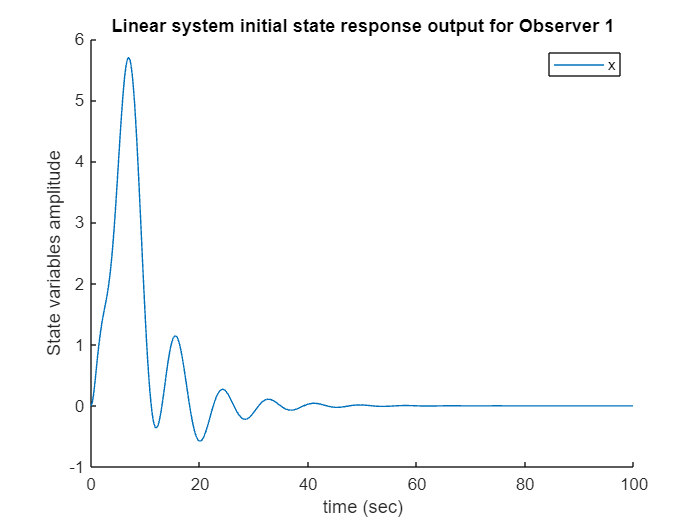

sys_1 = ss(A_c1, B_c, C_c1,D);%%MATLAB function to output statespace equations

op_lin1_init = initial(sys_1,X0,100); %In built function to give the response of the system to initial state


figure;
hold on
plot(tspan_lin_init(1:499),op_lin1_init(:,1))
ylabel('State variables amplitude')
xlabel('time (sec)')
title('Linear system initial state response output for Observer 1')
legend('x')

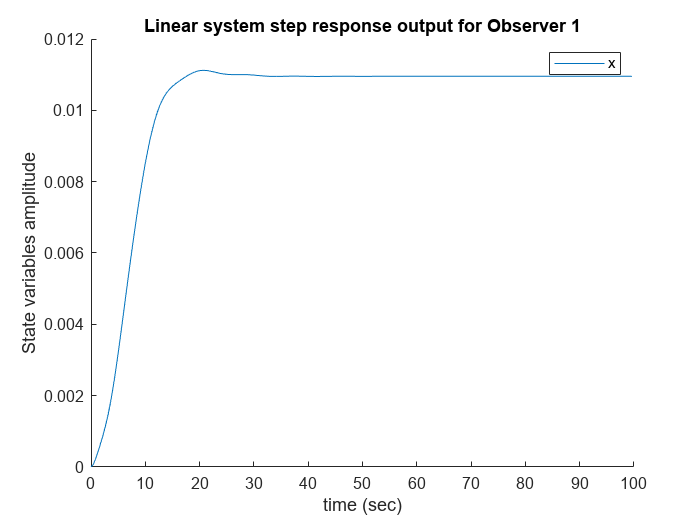


op_lin1_step = step(sys_1,100);%Gives the step response output

figure;
hold on
plot(tspan_lin_step(1:252),op_lin1_step(:,1))
ylabel('State variables amplitude')
xlabel('time (sec)')
title('Linear system step response output for Observer 1')
legend('x')

## Linear initial state and step response output for Observer 3

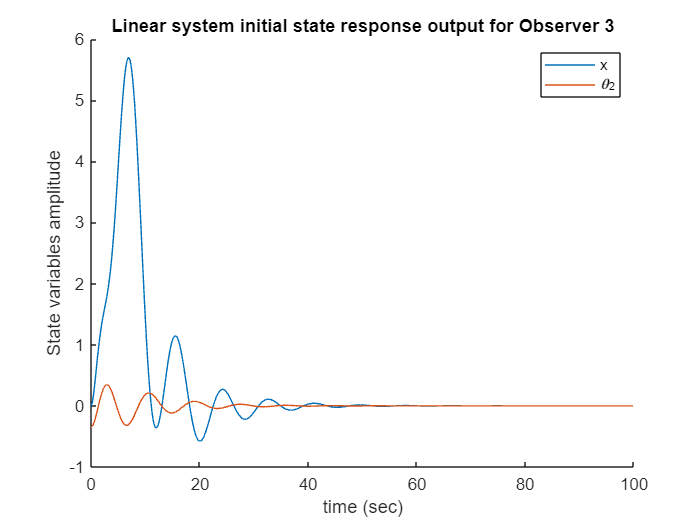

sys_3 = ss(A_c3, B_c, C_c3,D);%MATLAB function to output statespace equations

op_lin3_init = initial(sys_3,X0,100);%MATLAB inbuilt function to check the initial response of the system

figure;
hold on
plot(tspan_lin_init(1:499),op_lin3_init(:,1))
plot(tspan_lin_init(1:499),op_lin3_init(:,2))
ylabel('State variables amplitude')
xlabel('time (sec)')
title('Linear system initial state response output for Observer 3')
legend('x','\theta_2')

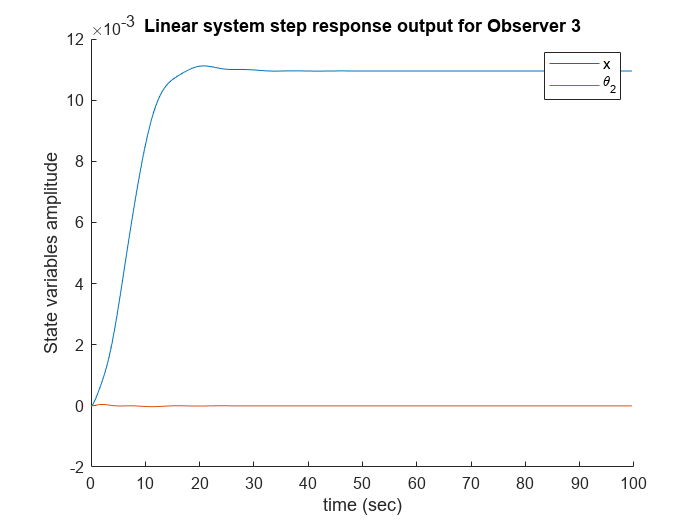


op_lin3_step = step(sys_3,100);%Gives the step response output

figure;
hold on
plot(tspan_lin_step(1:252),op_lin3_step(:,1))
plot(tspan_lin_step(1:252),op_lin3_step(:,2))
ylabel('State variables amplitude')
xlabel('time (sec)')
title('Linear system step response output for Observer 3')
legend('x','\theta_2')

## Linear initial state and step response output for Observer 4

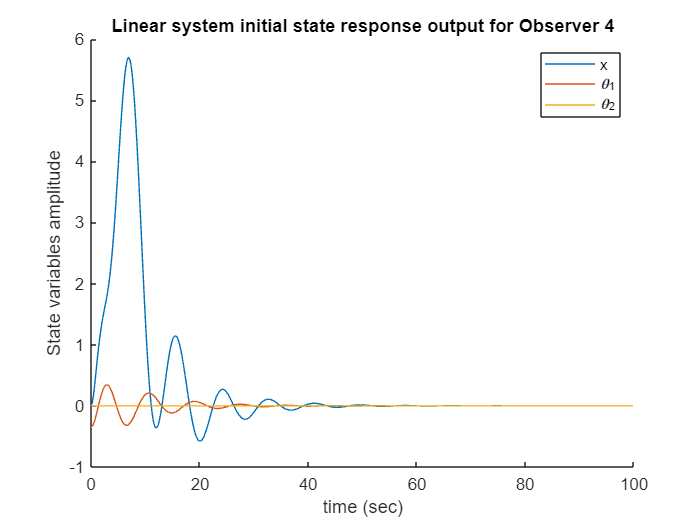

sys_4 = ss(A_c4, B_c, C_c4, D);%%MATLAB function to output statespace equations

op_lin4_init = initial(sys_4,X0,100);%MATLAB inbuilt function to check the initial response of the system

figure;
hold on
plot(tspan_lin_init(1:499),op_lin3_init(:,1))
plot(tspan_lin_init(1:499),op_lin3_init(:,2))
plot(tspan_lin_init(1:499),op_lin3_init(:,3))
ylabel('State variables amplitude')
xlabel('time (sec)')
title('Linear system initial state response output for Observer 4')
legend('x','\theta_1','\theta_2')

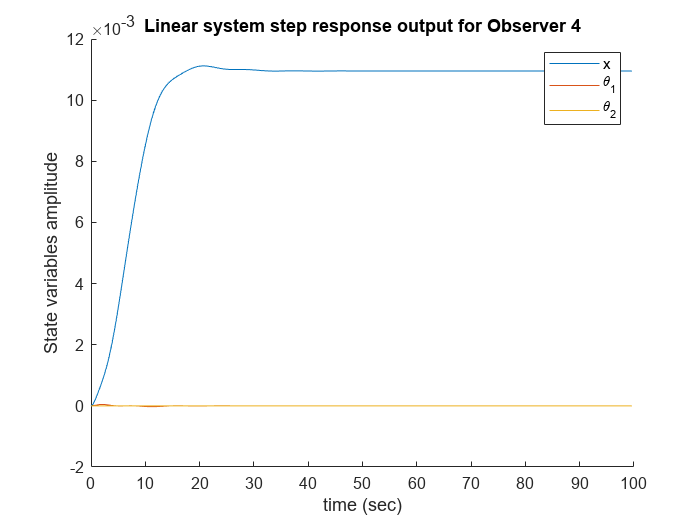


op_lin4_step = step(sys_4,100);%Gives the step response output

figure;
hold on
plot(tspan_lin_step(1:252),op_lin3_step(:,1))
plot(tspan_lin_step(1:252),op_lin3_step(:,2))
plot(tspan_lin_step(1:252),op_lin3_step(:,3))
ylabel('State variables amplitude')
xlabel('time (sec)')
title('Linear system step response output for Observer 4')
legend('x','\theta_1','\theta_2')

## Non-linear initial state response output for Observer 1

tspan = 0:0.01:100

tspan =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


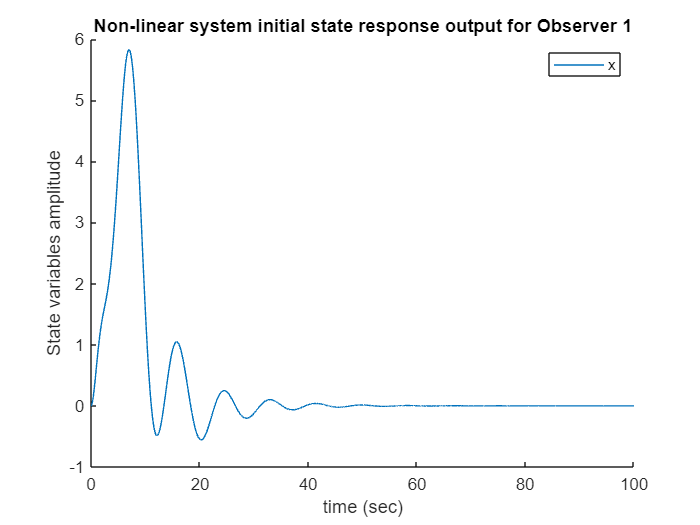


[t,y_nlinearobs1] = ode45(@(t,X)nlinear_obs(t,X,C1),tspan,X0);
figure;
hold on
plot(tspan,y_nlinearobs1(:,1))
ylabel('State variables amplitude')
xlabel('time (sec)')
title('Non-linear system initial state response output for Observer 1')
legend('x')

## Non-linear initial state response output for Observer 3

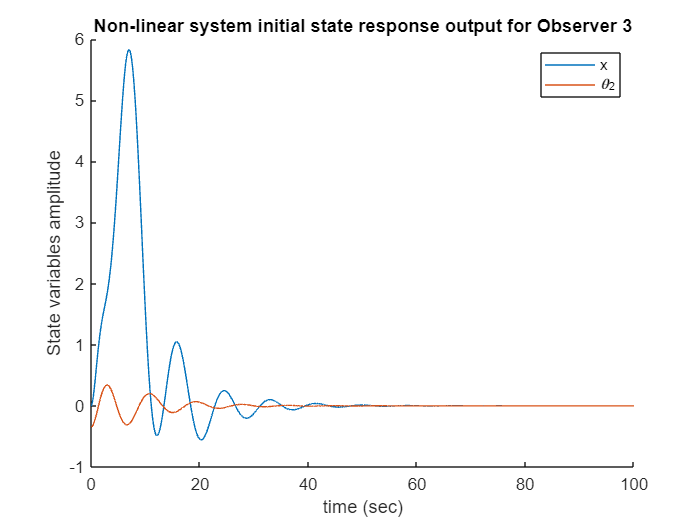

[t,y_nlinearobs3] = ode45(@(t,X)nlinear_obs(t,X,C3),tspan,X0);
figure;
hold on
plot(tspan,y_nlinearobs3(:,1))
plot(tspan,y_nlinearobs3(:,5))
ylabel('State variables amplitude')
xlabel('time (sec)')
title('Non-linear system initial state response output for Observer 3')
legend('x','\theta_2')

## Non-linear initial state response output for Observer 4

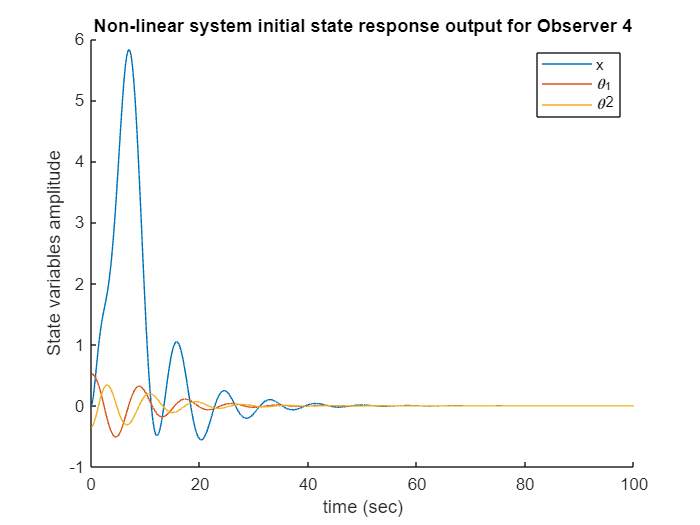

[t,y_nlinearobs4] = ode45(@(t,X)nlinear_obs(t,X,C4),tspan,X0);
figure;
hold on
plot(tspan,y_nlinearobs4(:,1))
plot(tspan,y_nlinearobs4(:,3))
plot(tspan,y_nlinearobs4(:,5))
ylabel('State variables amplitude')
xlabel('time (sec)')
title('Non-linear system initial state response output for Observer 4')
legend('x','\theta_1','\theta2')

## Function for non-linear observer

function dX = nlinear_obs(t,X,C)

M=1000; 
m1=100;
m2=100;
l1=20;
l2=10;
g=9.81;

A=[0 1 0 0 0 0; 
    0 0 -(m1*g)/M 0 -(m2*g)/M 0;
    0 0 0 1 0 0;
    0 0 -((M+m1)*g)/(M*l1) 0 -(m2*g)/(M*l1) 0;
    0 0 0 0 0 1;
    0 0 -(m1*g)/(M*l2) 0 -(g*(M+m2))/(M*l2) 0];

B=[0; 1/M; 0; 1/(M*l1); 0; 1/(M*l2)];

Q = [1/12 0 0 0 0 0;
    0 1/(12*0.1) 0 0 0 0;
    0 0 1/(8*0.2^2) 0 0 0;
    0 0 0 1/(12*0.01^2) 0 0;
    0 0 0 0 1/(8*0.2^2) 0;
    0 0 0 0 0 1/(12*0.01^2)];

R = 0.00001;

D = 0;

K_val = lqr(A,B,Q,R);

F=-K_val*X(1:6);
poles=[-3;-6;-9;-12;-15;-18];

L = place(A',C',poles)';

temp = (A-L*C)*X(7:12);

dX=zeros(12,1);

dX(1) = X(2);%DX;
dX(2)=(F-(g/2)*(m1*sin(2*X(3))+m2*sin(2*X(5)))-(m1*l1*(X(4)^2)*sin(X(3)))-(m2*l2*(X(6)^2)*sin(X(5))))/(M+m1*((sin(X(3)))^2)+m2*((sin(X(5)))^2));%DDX
dX(3)= X(4); %Dtheta1
dX(4)= (dX(2)*cos(X(3))-g*(sin(X(3))))/l1'; %DDtheta 1;
dX(5)= X(6); %Dtheta2
dX(6)= (dX(2)*cos(X(5))-g*(sin(X(5))))/l2; %DDtheta 2;
dX(7:12) = temp;
end